# Introduction to Constrained Nonlinear Minimization

Minimize the function 


$$\ln (1 + 3(y - (x^3 - x))^2 + (x - 4/3)^2)

$$


subject to upper and lower bounds.

clc; close all; clear all;

## Objective function

Create an anonymous function that returns the value of our expression. 

objfcn = @(x,y) log( 1 + 3*(y - (x.^3 - x)).^2 + (x - 4/3).^2 );

## Plot the objective

Plot it, changing the viewing angle.

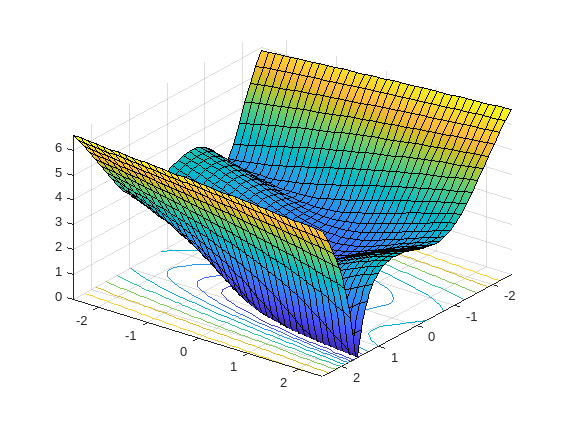

fsurf(objfcn,[-2.5 2.5],'ShowContours','on')
view(127,38)

## Problem

Create an optimization problem to hold the objective, constraints, and variables.

prob = optimproblem

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.


## Variables

Create optimization variables, giving each a display name to match their workspace names. Include the upper and lower bound constraints. They can also be specified with dot notation.

x = optimvar('x','LowerBound',-2.5,'UpperBound',2.5);
y = optimvar('y','LowerBound',-2.5,'UpperBound',2.5);

## Set optimization options, and optimize

Convert the objective function to an optimization expression. Variables that are in an expression of a problem are automatically added to the problem. 

prob.Objective = fcn2optimexpr(objfcn,x,y);

In this example, the function to use as the objective function was previously defined as a MATLAB function so it could be plotted. If the function were not already defined, we could specify it using an optimization expression as follows:

Define an initial point.

initialpt.x = -1;
initialpt.y = 2;

Create an options object suited to the type of objective and constraints by passing the problem to optimoptions. 

options = optimoptions(prob,'Display','iter','OutputFcn',@plotUpdate);

Solve the problem.

Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.914763e+00    0.000e+00    1.471e+00
    1       2    2.419836e+00    0.000e+00    9.189e-01    1.561e+00
    2       3    6.139243e-01    0.000e+00    1.675e+00    1.336e+00
    3       7    1.678726e-01    0.000e+00    2.819e-01    3.529e-01
    4       8    1.377951e-01    0.000e+00    2.362e-01    8.612e-02
    5       9    7.400878e-02    0.000e+00    1.214e+00    3.497e-01
    6      10    4.044422e-02    0.000e+00    1.826e+00    4.154e-01
    7      11    1.536770e-02    0.000e+00    1.617e+00    2.450e-01
    8      12    1.374722e-02    0.000e+00    4.634e-01    2.248e-01
    9      13    9.133605e-03    0.000e+00    1.337e-01    5.719e-02
   10      14    5.979460e-03    0.000e+00    1.367e-01    6.811e-02
   11      15    6.208147e-03    0.000e+00    7.919e-02    7.136e-03
   12      16   

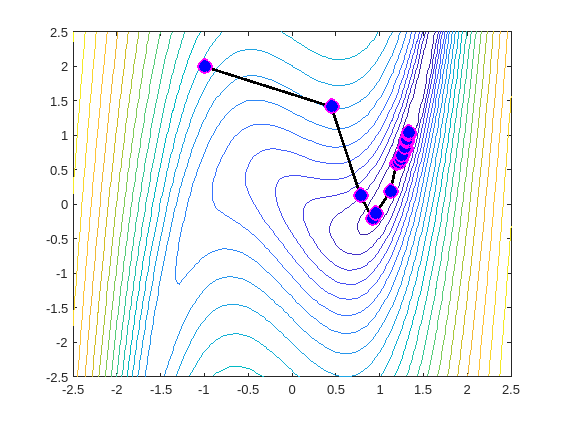


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[sol,fval,exitflag,output] = solve(prob,initialpt,'Options',options);

disp("# of function evaluations: " + output.funcCount)

# of function evaluations: 25


fval

fval = 9.1038e-15

sol

sol = struct with fields:
    x: 1.3333
    y: 1.0370


exitflag

exitflag =     OptimalSolution


## Optimizing with User-supplied gradient and Hessian

Many of the function evaluations are from the finite-difference calculation fmincon does in order to approximate the gradient, as seen below.

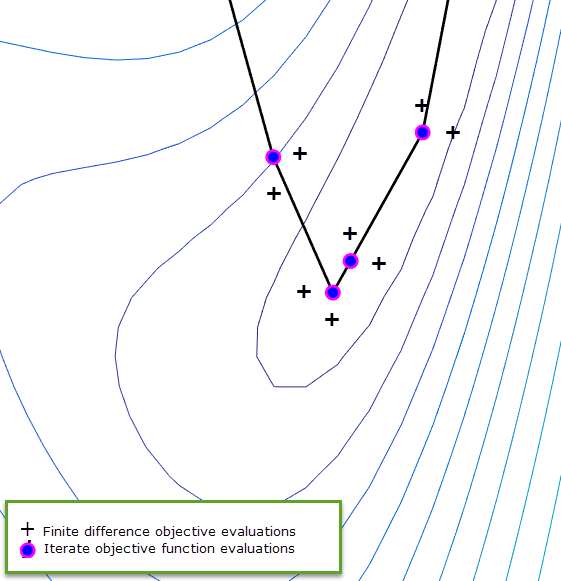

These extra function evaluations can take a considerable amount of time. This example problem only has 2 variables, but if you're solving a problem that has 50 variables, that's 50 extra function evaluations that fmincon has to do at each step. Luckily, there are 2 ways we can speed this up:

- Supply the solver with functions that calculate the gradient and Hessian 

- Use parallel computing (see 'UseParallel' option)

We'll focus on method 1 for now:

To use the gradient and Hessian, first convert the problem to solver-based form with `prob2struct`.

solverprob = prob2struct(prob);

The function returns a structure with problem data and generates a file named "generatedObjective.m" which computes the objective function. Edit this file where indicated to supply the gradient by calling the gradient function `gradfcn` .

edit generatedObjective.m

The file editedObjective.m is a saved copy of the edited file. Replace the `objective` field in the problem structure with the renamed function.

solverprob.objective = @editedObjective;

Set an initial point, options for supplying gradient and Hessian, and provide the Hessian function. 

solverprob.x0 = [-1; 2];

options.SpecifyObjectiveGradient = true;
options.HessianFcn = @hessfcn;
solverprob.options = options;

For this problem, the automatically selected solver is `fmincon`. Verify this by displaying the class of the options object. Solve using `fmincon`.

disp("Options class: " + class(options))

Options class: optim.options.Fmincon


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.914763e+00    0.000e+00    1.471e+00
    1       2    2.412621e+00    0.000e+00    1.053e+00    3.758e+00
    2       4    2.217630e+00    0.000e+00    3.614e+00    1.397e+00
    3       5    1.433305e+00    0.000e+00    1.408e+00    1.330e+00
    4       6    7.119473e-01    0.000e+00    6.041e+00    1.489e+00
    5       9    1.812676e-02    0.000e+00    1.560e+00    5.917e-01
    6      10    3.508223e-03    0.000e+00    3.260e-01    1.008e-01
    7      11    5.098325e-03    0.000e+00    8.079e-02    6.298e-02
    8      12    1.241915e-03    0.000e+00    1.285e-01    1.522e-01
    9      13    4.972600e-04    0.000e+00    1.684e-02    5.102e-02
   10      14    1.566087e-05    0.000e+00    3.711e-02    8.416e-02
   11      15    1.221381e-07    0.000e+00    4.275e-04    1.236e-02
   12      16    5.485131e-08    0.000e+00    1

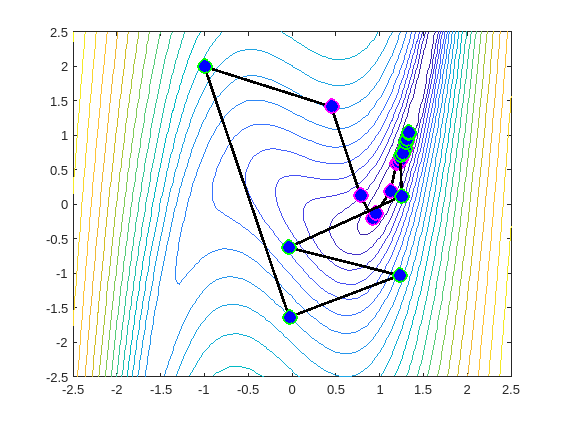


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[~,fval,exitflag,output] = fmincon(solverprob);

fval

fval = 2.3448e-13

exitflag

exitflag = 1

disp("# of function evaluations: " + output.funcCount)

# of function evaluations: 18


## Using Symbolic Math

Gradient and Hessian expressions can get quite long, even for this example. Alternatively, you can use Symbolic Math Toolbox to automatically calculate the gradient and Hessian functions for you.

Create symbolic variables.

syms xsym ysym

Define objective and use Symbolic Math functions for gradient and Hessian.

f = log( 1 + 3*(ysym - (xsym^3 - xsym))^2 + (xsym - 4/3)^2 );
g = gradient(f);
h = hessian(f);

Convert symbolic expressions into MATLAB functions. The functions group the variables into a single vector which is the format used in the solver-based approach.

obj = matlabFunction(f,'vars',{[xsym;ysym]});
grad = matlabFunction(g,'vars',{[xsym;ysym]});
hess = matlabFunction(h,'vars',{[xsym;ysym]});

Setup and run the optimization with the solver-based approach.The `deal` function returns the values from `obj` and `grad` in the form that `fmincon` requires. Pass the arguments to `fmincon` instead of using the problem structure.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.914763e+00    0.000e+00    1.471e+00
    1       2    2.412621e+00    0.000e+00    1.053e+00    3.758e+00
    2       4    2.217630e+00    0.000e+00    3.614e+00    1.397e+00
    3       5    1.433305e+00    0.000e+00    1.408e+00    1.330e+00
    4       6    7.119473e-01    0.000e+00    6.041e+00    1.489e+00
    5       9    1.812676e-02    0.000e+00    1.560e+00    5.917e-01
    6      10    3.508223e-03    0.000e+00    3.260e-01    1.008e-01
    7      11    5.098325e-03    0.000e+00    8.079e-02    6.298e-02
    8      12    1.241915e-03    0.000e+00    1.285e-01    1.522e-01
    9      13    4.972600e-04    0.000e+00    1.684e-02    5.102e-02
   10      14    1.566087e-05    0.000e+00    3.711e-02    8.416e-02
   11      15    1.221381e-07    0.000e+00    4.275e-04    1.236e-02
   12      16    5.485131e-08    0.000e+00    1

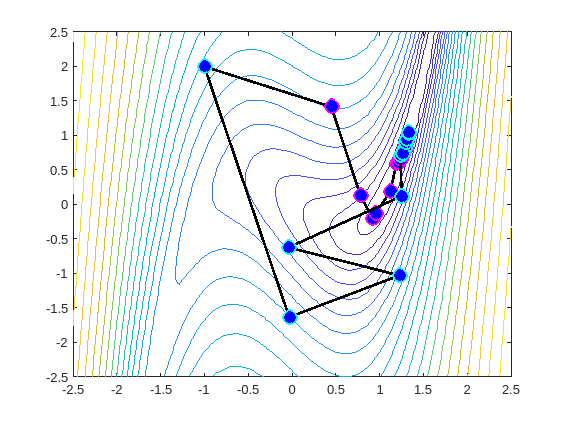


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


options = optimoptions('fmincon',...
    'SpecifyObjectiveGradient',true,...
    'HessianFcn',@(x,~)hess(x),...
    'Display','iter',...
    'outputfcn',@plotUpdate);

objAndGrad = @(x) deal(obj(x),grad(x));

[~,fval,exitflag,output] = fmincon(objAndGrad,[-1;2],[],[],[],[],...
    solverprob.lb,solverprob.ub,[],options);  

fval

fval = 2.3426e-13

exitflag

exitflag = 1

disp("# of function evaluations: " + output.funcCount)

# of function evaluations: 18


Copyright 2010-2019, The MathWorks, Inc.